Tyler Barbero

SIO175 HW3

Problem 1

Plot time series of u (positive east) and v(positive north) current components for all depths.

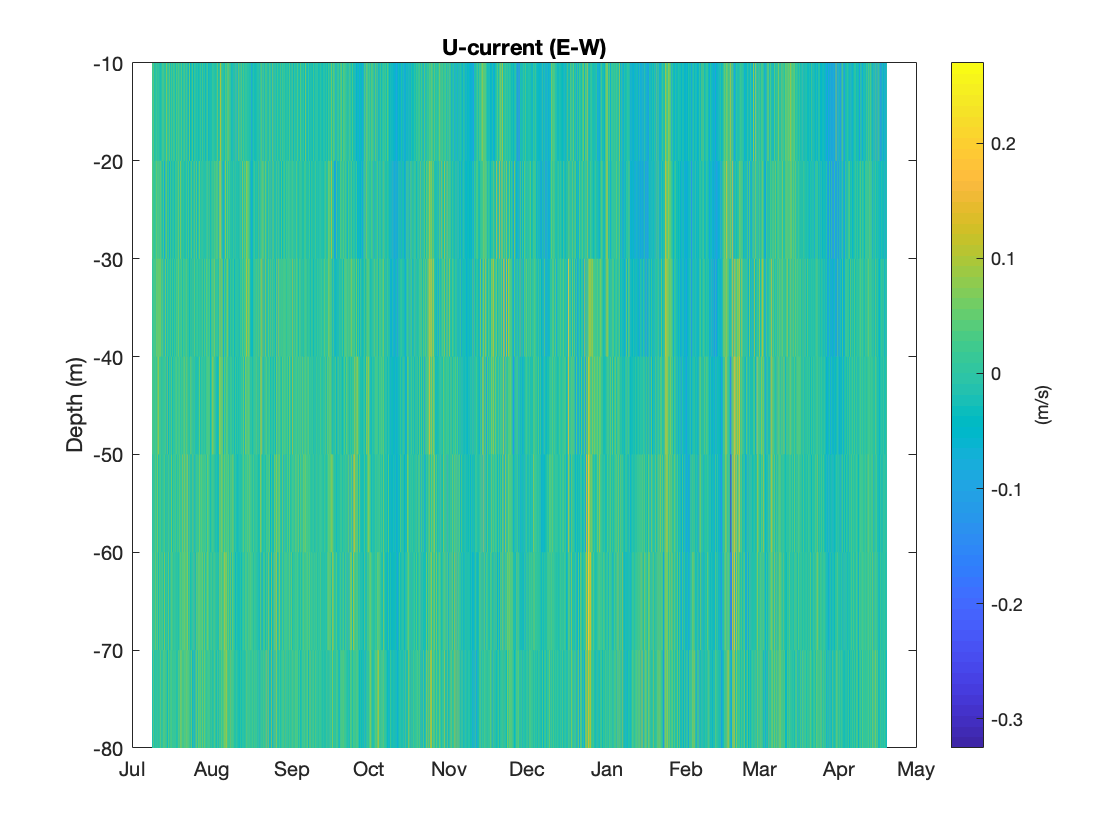

clc;clear;close 
load DelMar_data.mat;
nt = length(t);
% we have time, depth, and speed as variables use contourf plot
tmp = pcolor(t,z,u);
set(tmp,'EdgeColor','None')
datetick;
c = colorbar;
c.Label.String = '(m/s)';
ylabel('Depth (m)')
title('U-current (E-W)')

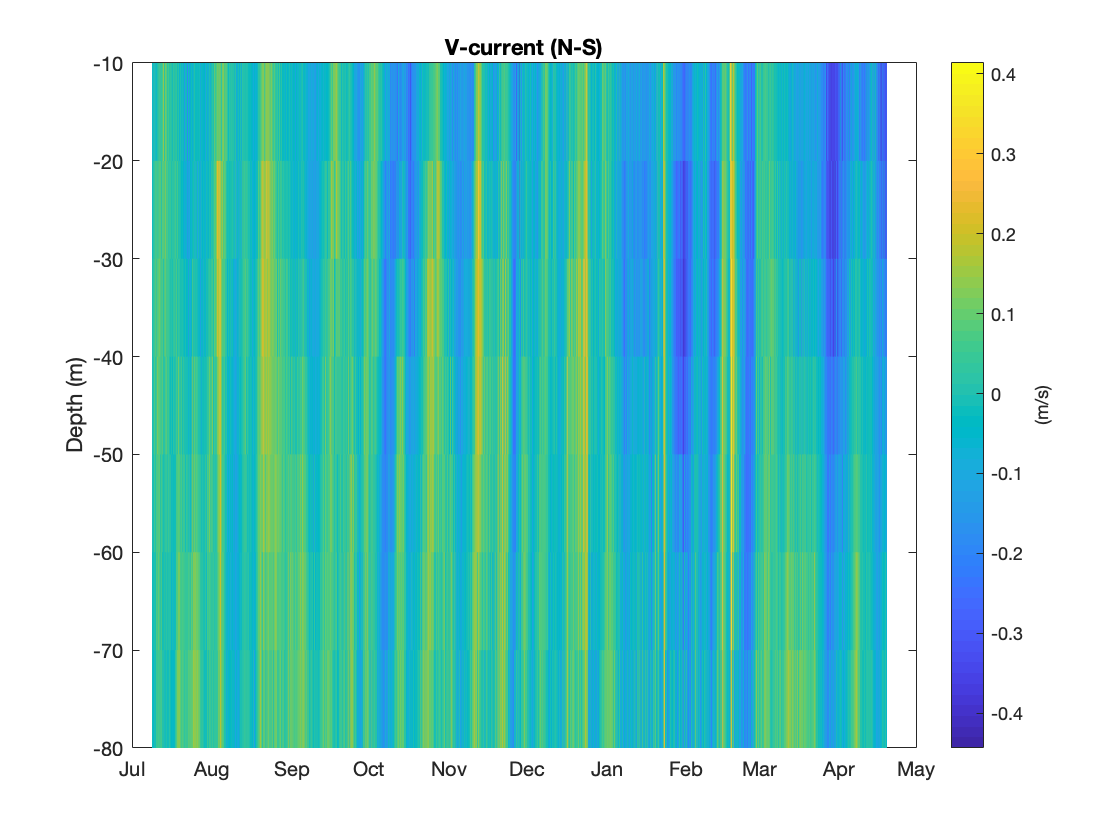

tmp = pcolor(t,z,v);
set(tmp,'EdgeColor','None')
datetick;
c = colorbar;
c.Label.String = '(m/s)';
ylabel('Depth (m)')
title('V-current (N-S)')

Problem 2	

Plot current time series as vector plots using quiver.

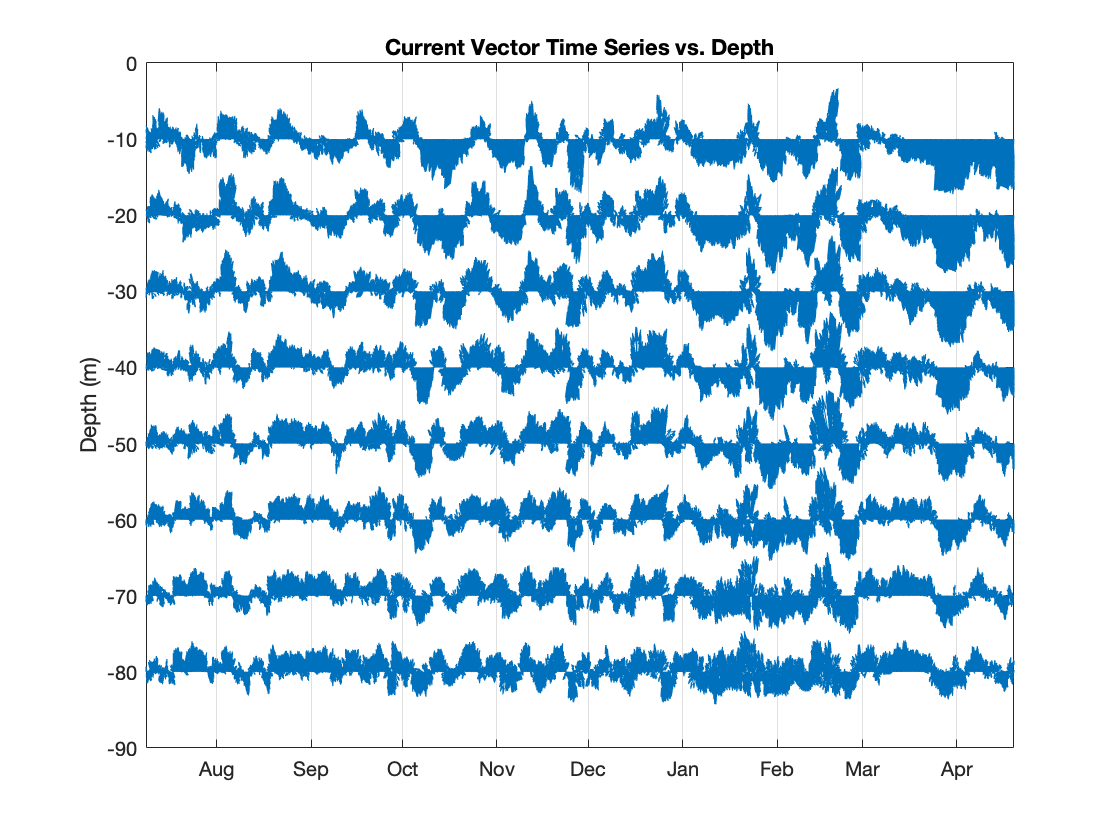

quiver(t,z,u,v)
datetick
xlim([t(1),t(end)])
ylabel('Depth (m)')
grid;title('Current Vector Time Series vs. Depth')

Problem 3

Compute EOFs of the combined u and v currents (scalar, not vector). 

uu = [u;v]; % need to do uu' --> detrend acts on columns of uu
uu = detrend(uu',0)'; % get anomaly matrix by taking out mean

% form the covariance matrix by multiplying data by eachother
C = 1/(nt-1)*(uu*uu'); % C is nt x nt - we summed over time; this is 
% called the spatial covariance matrix (16x16) = (nzxnz)
[e,lambda] = eig(C); % e is the eigenvectors
lambda = diag(lambda);
lambda = flipud(lambda);
e = fliplr(e);
pvar = lambda/sum(lambda)*100;

Problem 4

Plot percent total variance of each mode vs mode number

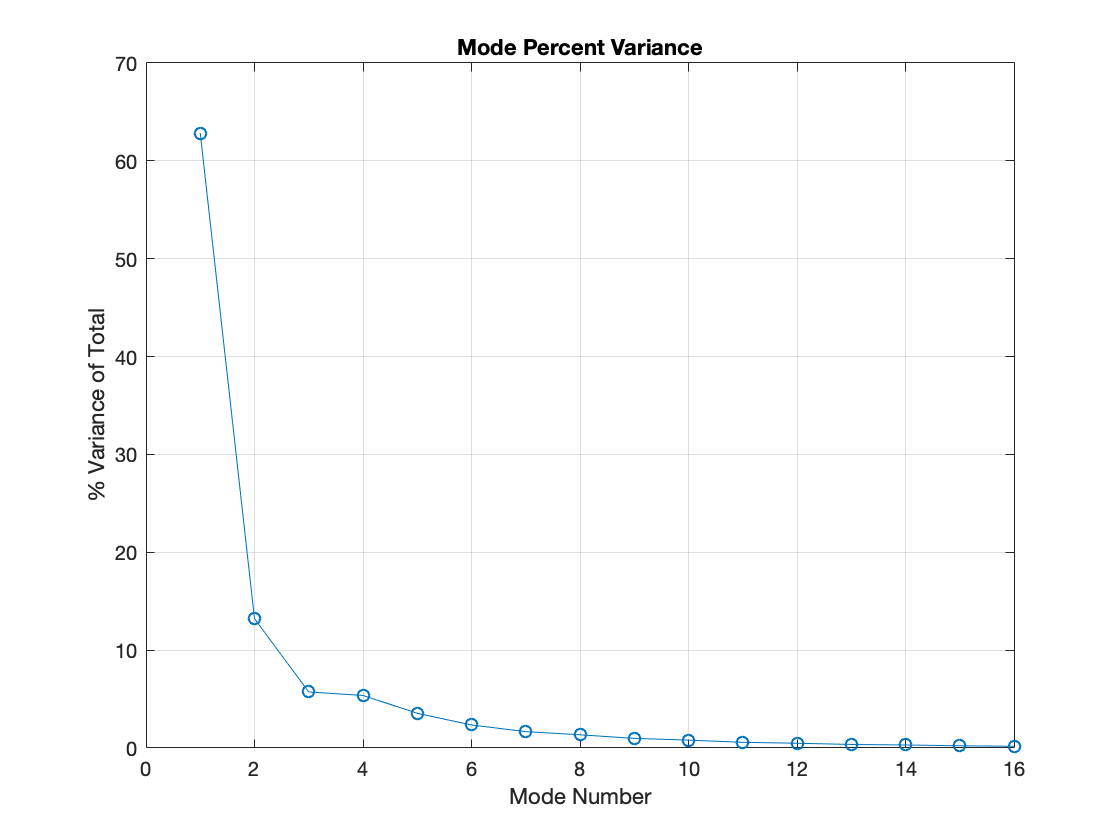

plot(pvar,'-o');grid
xlabel('Mode Number');ylabel('% Variance of Total')
title('Mode Percent Variance')

Problem 5

Plot the EOFS (depth patterns) of the first 3 modes

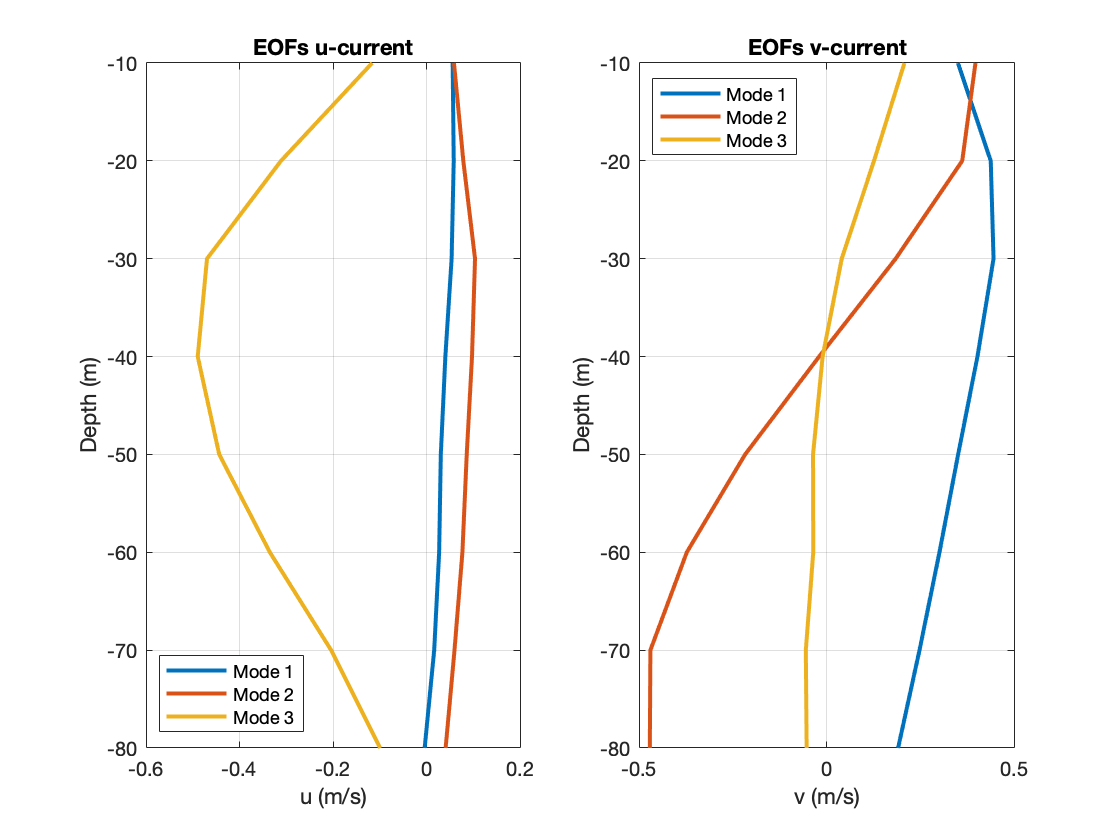

subplot(1,2,1)
plot(e(1:8,1:3),z,'linewidth',2);grid
xlabel('u (m/s)');ylabel('Depth (m)')
title('EOFs u-current')
legend('Mode 1','Mode 2','Mode 3','Location','SW')
subplot(1,2,2)
plot(e(9:16,1:3),z,'linewidth',2);grid
xlabel('v (m/s)');ylabel('Depth (m)')
title('EOFs v-current')
legend('Mode 1','Mode 2','Mode 3','Location','NW')

Problem 6

Plot the PCs (temporal expansions) of the first 3 modes.

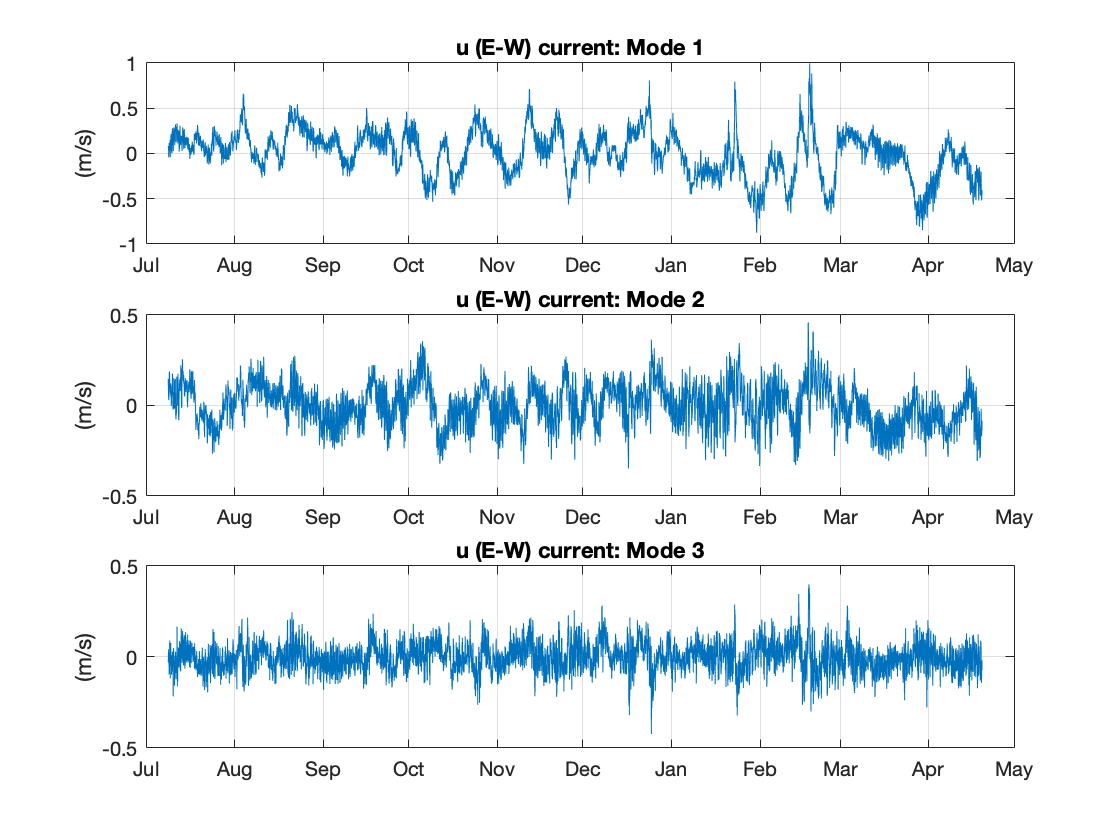

% get PC's (time series) by projecting eigenvectors (e) onto original data
A = uu'*e; % e is  a basis for the covariance matrix that we project onto
% the original data to get the time series of each mode
for i=1:3
figure(1)
subplot(3,1,i)
plot(t,A(:,i));grid;
ylabel('(m/s)')
title(['u (E-W) current: Mode ' num2str(i)])
datetick
end

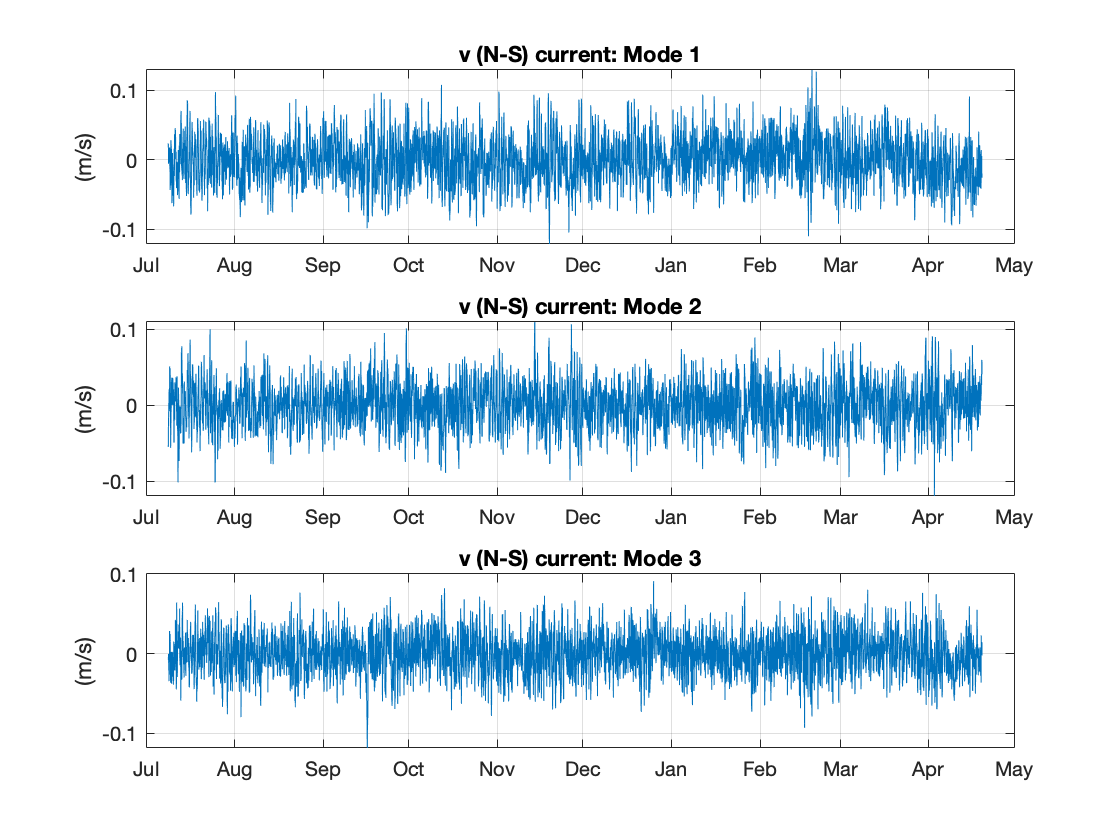

for i=9:11
figure(2)
subplot(3,1,i-8)
plot(t,A(:,i));grid;
ylabel('(m/s)')
title(['v (N-S) current: Mode ' num2str(i-8)])
datetick
end

***There are 16 modes, and each of them describes both u and v - the 1st PC multiplies both the u and v components of the 1st mode, and so on. Also one of either the PCs or the modes needs to be unitless - you multiply them together and want to get m/s.***

***0.25/1***

Problem 7

For each current time series, compute the percent variance accounted for by each of the first 3 modes. Plot these percentages as a function of depth.

pvarm = NaN(16,8);
for i=1:16
    for j=1:16 % modes, 8 modes for u; 8 modes for v
        tmp = A(:,j)*e(i,j);
        pvarm(i,j) = var(tmp)/var(uu(i,:))*100;
%         % looking at Hint:
%         tvar = sum(lambda(j)*(e(j,:).^2));
%         pvarm(j,i) = (lambda(j) * e(j,i)^2)/(e(j,:).^2 * lambda)*100;
    end
end
disp(sum(pvarm'))

  Columns 1 through 9

  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000

  Columns 10 through 16

  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000



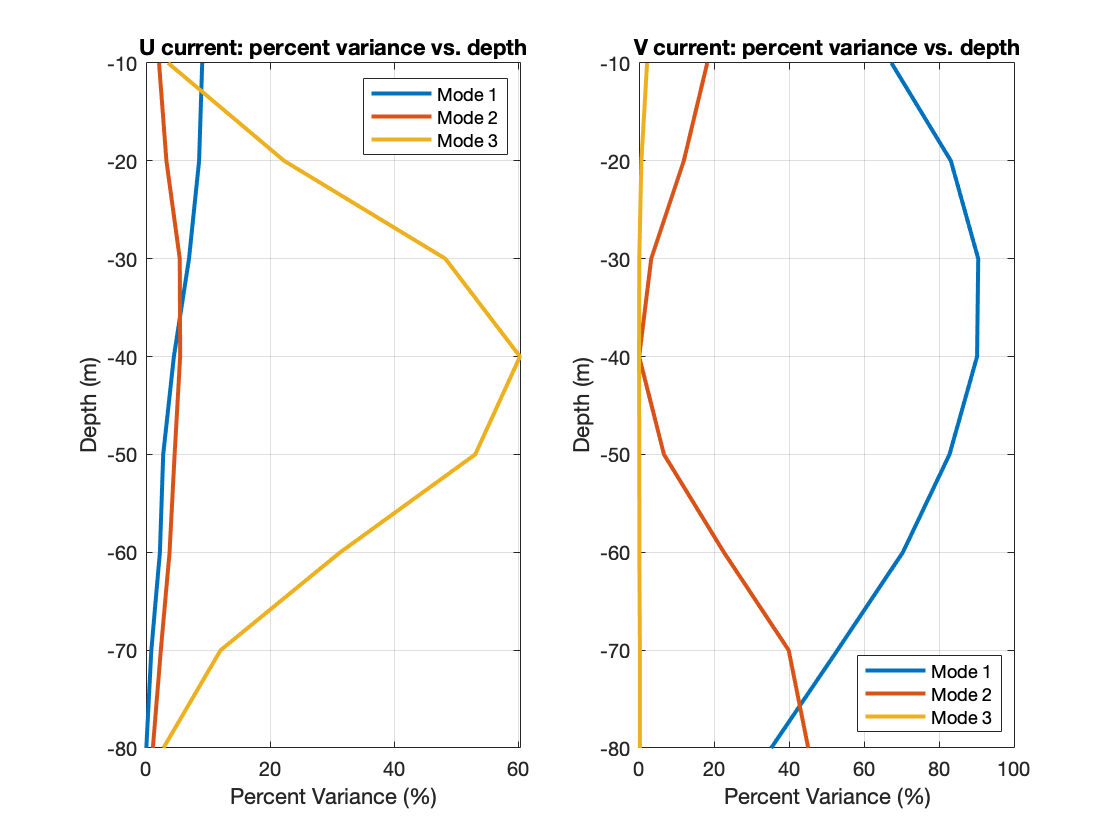

% plot percent variance (depth)
subplot(1,2,1)
plot(pvarm(1:8,1:3),z,'linewidth',2)
legend('Mode 1','Mode 2','Mode 3')
title('U current: percent variance vs. depth')
xlabel('Percent Variance (%)');grid
ylabel('Depth (m)')
subplot(1,2,2)
plot(pvarm(9:16,1:3),z,'linewidth',2)
legend('Mode 1','Mode 2','Mode 3','Location','SE')
title('V current: percent variance vs. depth')
ylabel('Depth (m)')
xlabel('Percent Variance (%)');grid

Problem 8			

Discuss the results of the EOF analysis. What aspects of the current variability are captured in the first 3 modes? 

Summary: We perform an EOF analysis by combining the u,v components of current into one matrix (16x13682).  Then get the anomaly by removing the mean. Then form the covariance matrix by multiplying the vector times itself, (We're asked to make the EOFs the depth patterns so we need to sum over time and get the spatial covariance matrix: if uu = 16x13682, do uu*uu' to get 16x16).

The first mode (blue) shows no variability in the u (E-W) direction but a decent amount of the signal is dominated by the v current (N-S) through the depth of the layer. We see the blue line is positive and decently high in magnitude (~0.3m/s) through the depth of the layer, indicating a Northward (alonghsore) flow at DelMar.

The second mode (red) doesn't show much dominance of the signal for the u-component, while the v-component does. In fact, we see a northward flow from -10 to -40m depth then it switches to a southward flow at -40 to -80m depth.

The third mode (yellow) sees a huge dominance of the signal in the u-current (E-W) mainly in the middle depths (-40 -50 -60m) then tapers off to above and below these depths. No signal really in the v-current for mode 3 (except for a bit at the surface).

In terms of pecent variability for u-current, we see a mode 3 dominates most of the variability in the u-current (mostly at the middle depths (-30 -40 -50 -60m). Modes 1 and 2 have some signal but are relatively small. 

For v-current the percent variability of N-S flow is dominated by mode 1 and somewhat mode 2 but moreso at the bottom.